## 复值符号差错模型

#### 参数设置

clearvars;
close all;
clc;
rng(2023);  %固定随机种子，保证结果可复现

% 参数
% 信噪比范围 E_s/\sigma^2
snr_dB = 0:1:25;                %信噪比0~25dB
snr = 10.^(snr_dB/10);

% 符号数
M = [4;16];

% 重复实验次数，可修改
N = 1e4;

### 计算

% 随机生成符号序列
%两个2×26矩阵，对应所有的M×snr情况
ber = zeros(length(M),length(snr));
ser = zeros(length(M),length(snr));
for cnt1 = 1:length(M)
    % 生成bit序列（bit_data）
    if M(cnt1)==4
        bit_data = randi([0 1], 1, 2*N); % 2N个bit，N个符号
    elseif M(cnt1)==16
        bit_data = randi([0 1], 1, 4*N); % 4N个bit，N个符号
    else
        error('Invalid modulation order');
    end

    % 转化为符号映射后的离散符号序列（mod_data）
    if M(cnt1)==4
        mod_data = my_gray_map_complex_M4(bit_data);
        % 理论平均符号能量
        Es_theory = 2*(4-1)/3;
    elseif M(cnt1)==16
        mod_data = my_gray_map_complex_M16(bit_data);
        % 理论平均符号能量
        Es_theory = 2*(16-1)/3;
    end

    % 发送端平均符号能量
    Es = (sum(abs(mod_data).^2))/N;           

    for cnt2 = 18:18
        % 加性噪声
        noise_power = Es/snr(cnt2);
        noise = normrnd(0,sqrt(noise_power),size(mod_data))+normrnd(0,sqrt(noise_power),size(mod_data))*1j;

        % 加性高斯噪声信道，获得接收信号（rx_data）
        rx_data = mod_data + noise;

        % 解调，根据符号序列获得bit序列（demod_bit_data）
        if M(cnt1)==4
            demod_bit_data = my_inverse_gray_map_complex_M4(rx_data);
        elseif M(cnt1)==16
            demod_bit_data = my_inverse_gray_map_complex_M16(rx_data);
        end

        % 差错比特
        bit_err = xor(bit_data, demod_bit_data);
        % 计算差错比特数
        ber(cnt1,cnt2) = sum(bit_err);
        % 计算差错符号数
        bit_err = reshape(bit_err,[],N);
        ser(cnt1,cnt2) = sum(any(bit_err,1));
    end
end
% 误码率和误比特率归一化
% ber = ber./(N*([2;4]*ones(1,26)));
% ser = ser./N;

% 理论值
ser_theory(1,:) = 2*qfunc(sin(pi/M(1,:))*sqrt(snr));
ser_theory(2,:) = 4*((M(2,:)-sqrt(M(2,:)))./M(2,:))*ones(1,26).*qfunc(sqrt((3./(2*(M(2,:)-1)))*snr));
ber_theory = ser_theory./log2(M);

### 绘图

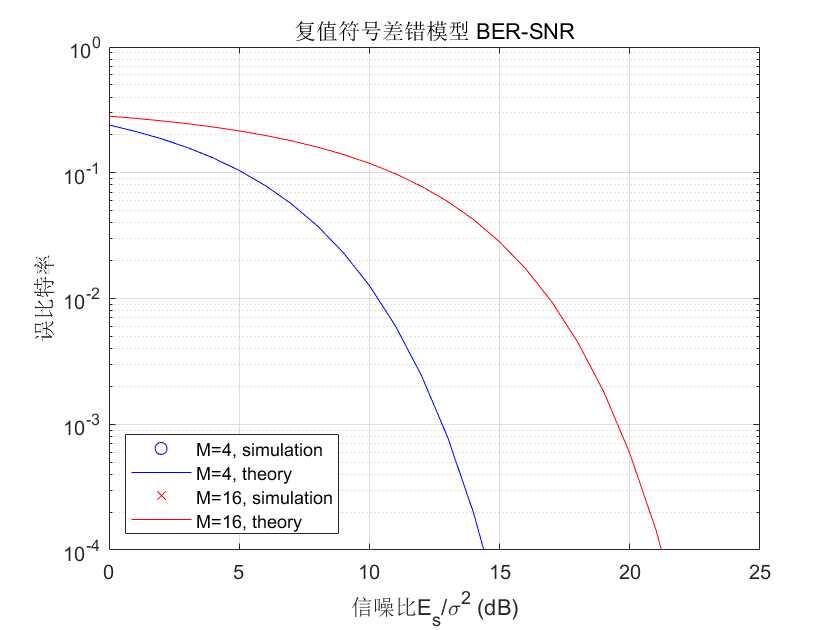

figure;
semilogy(snr_dB, ber(1,:),'bo', ...
    snr_dB, ber_theory(1,:),'b', ...
    snr_dB, ber(2,:),'rx', ...
    snr_dB, ber_theory(2,:),'r');
xlabel('信噪比E_s/\sigma^2 (dB)');
ylabel('误比特率');
set(gca, 'ylim', [1e-4,1e0]);
legend('M=4, simulation', 'M=4, theory', ...
    'M=16, simulation', 'M=16, theory', ...
    'Location', 'southwest');
title('复值符号差错模型 BER-SNR');
box on;
grid on;

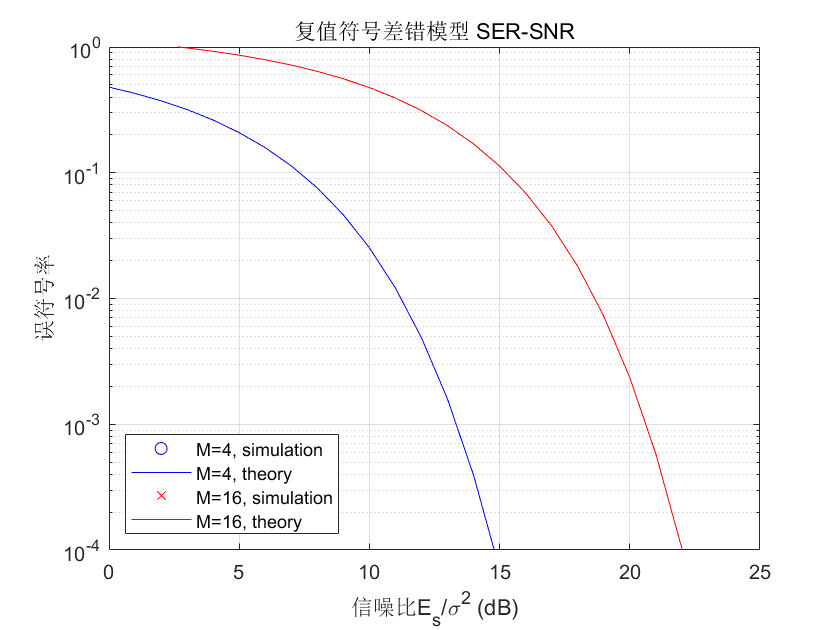


figure;
semilogy(snr_dB, ser(1,:),'bo', ...
    snr_dB, ser_theory(1,:),'b', ...
    snr_dB, ser(2,:),'rx', ...
    snr_dB, ser_theory(2,:),'r');
xlabel('信噪比E_s/\sigma^2 (dB)');
ylabel('误符号率');
set(gca, 'ylim', [1e-4,1e0]);
legend('M=4, simulation', 'M=4, theory', ...
    'M=16, simulation', 'M=16, theory', ...
    'Location', 'southwest');
title('复值符号差错模型 SER-SNR');
box on;
grid on;

### 格雷映射函数

复值符号差错模型，M=4，由bit序列映射到离散符号

function mod_data = my_gray_map_complex_M4(bit_data)
if mod(length(bit_data),2)==0
    % 对应的符号序列长度
    N = length(bit_data)/2;
    mod_data = zeros(1,N);
    % 逐个符号判断映射关系
    for n = 1:N
        current_bits = bit_data(2*n-1 : 2*n);
        if current_bits(1)==0 && current_bits(2)==0
            mod_data(n) = 1;
        elseif current_bits(1)==0 && current_bits(2)==1
            mod_data(n) = 1j;
        elseif current_bits(1)==1 && current_bits(2)==1
            mod_data(n) = -1;
        elseif current_bits(1)==1 && current_bits(2)==0
            mod_data(n) = -1j;
        end
    end
else
    error('Invalid modulation order');
end
end

 复值符号差错模型，M=16，由bit序列映射到离散符号

function mod_data = my_gray_map_complex_M16(bit_data)
if mod(length(bit_data),4)==0
    % 对应的符号序列长度
    N = length(bit_data)/4;
    mod_data = zeros(1,N);
    % 逐个符号判断映射关系
    for n = 1:N
        current_bits = bit_data(4*n-3 : 4*n);
        if all(current_bits==[0,0,0,0])
            mod_data(n) = 3+3j;
        elseif all(current_bits==[0,0,0,1])
            mod_data(n) = 1+3j;
        elseif all(current_bits==[0,0,1,1])
            mod_data(n) = -1+3j;
        elseif all(current_bits==[0,0,1,0])
            mod_data(n) = -3+3j;
        elseif all(current_bits==[0,1,0,0])
            mod_data(n) = 3+1j;
        elseif all(current_bits==[0,1,0,1])
            mod_data(n) = 1+1j;
        elseif all(current_bits==[0,1,1,1])
            mod_data(n) = -1+1j;
        elseif all(current_bits==[0,1,1,0])
            mod_data(n) = -3+1j;
        elseif all(current_bits==[1,1,0,0])
            mod_data(n) = 3-1j;
        elseif all(current_bits==[1,1,0,1])
            mod_data(n) = 1-1j;
        elseif all(current_bits==[1,1,1,1])
            mod_data(n) = -1-1j;
        elseif all(current_bits==[1,1,1,0])
            mod_data(n) = -3-1j;
        elseif all(current_bits==[1,0,0,0])
            mod_data(n) = 3-3j;
        elseif all(current_bits==[1,0,0,1])
            mod_data(n) = 1-3j;
        elseif all(current_bits==[1,0,1,1])
            mod_data(n) = -1-3j;
        elseif all(current_bits==[1,0,1,0])
            mod_data(n) = -3-3j;
        end
    end
else
    error('Invalid modulation order');
end
end

复值符号差错模型，M=4，由离散符号映射到bit序列

function demod_bit_data = my_inverse_gray_map_complex_M4(rx_data)
% 符号序列长度
N = length(rx_data);
demod_bit_data = zeros(1,2*N);
% 逐个符号判决
for n = 1:N
    if angle(rx_data(n))>=pi/4&&angle(rx_data(n))<=3*pi/4
        demod_bit_data(2*n-1:2*n) =[0 1];
    elseif angle(rx_data(n))>=3*pi/4||angle(rx_data(n))<=-3*pi/4
        demod_bit_data(2*n-1:2*n) =[1 1];
    elseif angle(rx_data(n))>=-3*pi/4&&angle(rx_data(n))<=-pi/4
        demod_bit_data(2*n-1:2*n) =[1 0];
    elseif angle(rx_data(n))>=-pi/4&&angle(rx_data(n))<=pi/4
        demod_bit_data(2*n-1:2*n) =[0 0];
    end
end
end

复值符号差错模型，M=16，由离散符号映射到bit序列

function demod_bit_data = my_inverse_gray_map_complex_M16(rx_data)
% 符号序列长度
N = length(rx_data);
demod_bit_data = zeros(1,4*N);
% 逐个符号判决
for n = 1:N
    %四个角点
    if (real(rx_data(n))>=2) && (imag(rx_data(n))>=2)
        demod_bit_data(4*n-3:4*n) =[0 0 0 0];
    elseif (real(rx_data(n))<=-2) && (imag(rx_data(n))>=2)
        demod_bit_data(4*n-3:4*n) =[0 0 1 0];
    elseif (real(rx_data(n))<=-2) && (imag(rx_data(n))<=-2)
        demod_bit_data(4*n-3:4*n) =[1 0 1 0];
    elseif (real(rx_data(n))>=2) && (imag(rx_data(n))<=-2)
        demod_bit_data(4*n-3:4*n) =[1 0 0 0];
    %八个边点
    elseif (real(rx_data(n))>=0&&real(rx_data(n))<=2) && (imag(rx_data(n))>=2)
        demod_bit_data(4*n-3:4*n) =[0 0 0 1];
    elseif (real(rx_data(n))<=0&&real(rx_data(n))>=-2) && (imag(rx_data(n))>=2)
        demod_bit_data(4*n-3:4*n) =[0 0 1 1];
    elseif (real(rx_data(n))<=0&&real(rx_data(n))>=-2) && (imag(rx_data(n))<=-2)
        demod_bit_data(4*n-3:4*n) =[1 0 1 1];
    elseif (real(rx_data(n))>=0&&real(rx_data(n))<=2) && (imag(rx_data(n))<=-2)
        demod_bit_data(4*n-3:4*n) =[1 0 0 1];
        
    elseif (real(rx_data(n))>=2) && (imag(rx_data(n))>=0&&imag(rx_data(n))<=2)
        demod_bit_data(4*n-3:4*n) =[0 1 0 0];
    elseif (real(rx_data(n))>=2) && (imag(rx_data(n))<=0&&imag(rx_data(n))>=-2)
        demod_bit_data(4*n-3:4*n) =[1 1 0 0];
    elseif (real(rx_data(n))<=-2) && (imag(rx_data(n))>=0&&imag(rx_data(n))<=2)
        demod_bit_data(4*n-3:4*n) =[0 1 1 0];
    elseif (real(rx_data(n))<=-2) && (imag(rx_data(n))<=0&&imag(rx_data(n))>=-2)
        demod_bit_data(4*n-3:4*n) =[1 1 1 0];
    %四个中央点
    elseif (real(rx_data(n))>=0&&real(rx_data(n))<=2) && (imag(rx_data(n))>=0&&imag(rx_data(n))<=2)
        demod_bit_data(4*n-3:4*n) =[0 1 0 1];
    elseif (real(rx_data(n))<=0&&real(rx_data(n))>=-2) && (imag(rx_data(n))>=0&&imag(rx_data(n))<=2)
        demod_bit_data(4*n-3:4*n) =[0 1 1 1];
    elseif (real(rx_data(n))<=0&&real(rx_data(n))>=-2) && (imag(rx_data(n))<=0&&imag(rx_data(n))>=-2)
        demod_bit_data(4*n-3:4*n) =[1 1 1 1];
    elseif (real(rx_data(n))>=0&&real(rx_data(n))<=2) && (imag(rx_data(n))<=0&&imag(rx_data(n))>=-2)
        demod_bit_data(4*n-3:4*n) =[1 1 0 1];
    end
end
end